Author: Zarina Akbary

Date: 28 May 2021

Purpose: to walk throug BacTrack.m line by line

## BacTrack.m

Purpose: tracks bacterial growth from phase image stacks. This script is customized for B.subtilis. BacTrack2.m is customized for B.subtilis filaments.

Instructions for use:

Outputs:

Calls on the following m-files:

User inputs:

### Section 1: User Inputs

clear, close all %clear all variables in the workspace and close all existing figures
tic %start stopwatch timer

%%User Input
basename='05082021_Exp5_colony1';%Name of the image stack, used to save file.
dirname=['/Users/zarina/Downloads/NYU/Year2_2021_Spring/05082021_analysis/' basename '/' basename '_phase/'  basename '_erased'];%Directory that the image stack is saved in.
savedir=['/Users/zarina/Downloads/NYU/Year2_2021_Spring/05082021_analysis/' basename '/' basename '_phase/'  basename '_figures'];%Directory to save the output .mat file to.
lscale=0.08;%%Microns per pixel (it's shown on the Nikon software at the bottom left of the window)
tscale=10;%Frame rate, frames per second
thresh=0;%For default, enter zero.
IntThresh=20000;%Threshold used to enhance contrast. Default:35000
dr=1;%Radius of dilation before watershed 
sm=2;%Parameter used in edge detection
minL=2;%Minimum cell length
minW=0.2;%Minimum cell width
maxW=1.5;%Maximum cell width
minA=50;%Minimum cell area. default 50
cellLink=4;%Number of frames to ignore missing cells when tracking frame to frame
recrunch=0;%Display data from previously crunched data? 0=No, 1=Yes.
vis=1;%Display cell tracking? 0=No, 1=Yes.
checkhist=1;%Display image histogram? 0=No, 1=Yes.

## Identifying cells

In the actual BacTrack script, there is an if-else statement based on recrunch. If recrunch==1, then it will load the variables in the stored .mat file. If recrunch==0, then we will go through the following operations.

First, we determine the number of frames by going to the directory and finding all the files with a .tif extension.

%Determine number of frames
curdir=cd;
cd(dirname);
directory=dir('*.tif');
T=length(directory);

cd(curdir);
path(dirname,path)

Now, we pre-allocate many variables. Notice how they are all seeded with zero and not NaN.

nc=zeros(1,T);
allcentroids=[];
cellnum=[];
tstamp=[];

%Pre-allocate matrices
ewav=zeros(1,T);
ewstd=zeros(1,T);
ewste=zeros(1,T);
ewndp=zeros(1,T);
wav=zeros(1,T);
wstd=zeros(1,T);
wste=zeros(1,T);
vav=zeros(1,T-1);
vstd=zeros(1,T-1);
vste=zeros(1,T-1);
ndp=zeros(1,T-1);
avav=zeros(1,T-1);
avstd=zeros(1,T-1);
avste=zeros(1,T-1);
a=zeros(1,T);
w=zeros(1,T);
l=zeros(1,T);
DS=zeros(1,T);
boun=cell(1,T);
pole=zeros(1,T);
mline=cell(1,T);

Now, we load the first image to get its dimensions and to preallocate our labels matrix.

%Load first image
imagename=directory(1).name;
im=imread(imagename);
[imM,imN]=size(im);
labels=zeros(imM,imN,T);
labels2=zeros(imM,imN,T);

After this, the for loop begins and we go through all the images in the image stack. However, for the purpose of this demonstration, we will walk through the tracking of cells in the first image.

t=1;
    
%Load image
imagename=directory(t).name;

im=imread(imagename);
[imM,imN]=size(im);

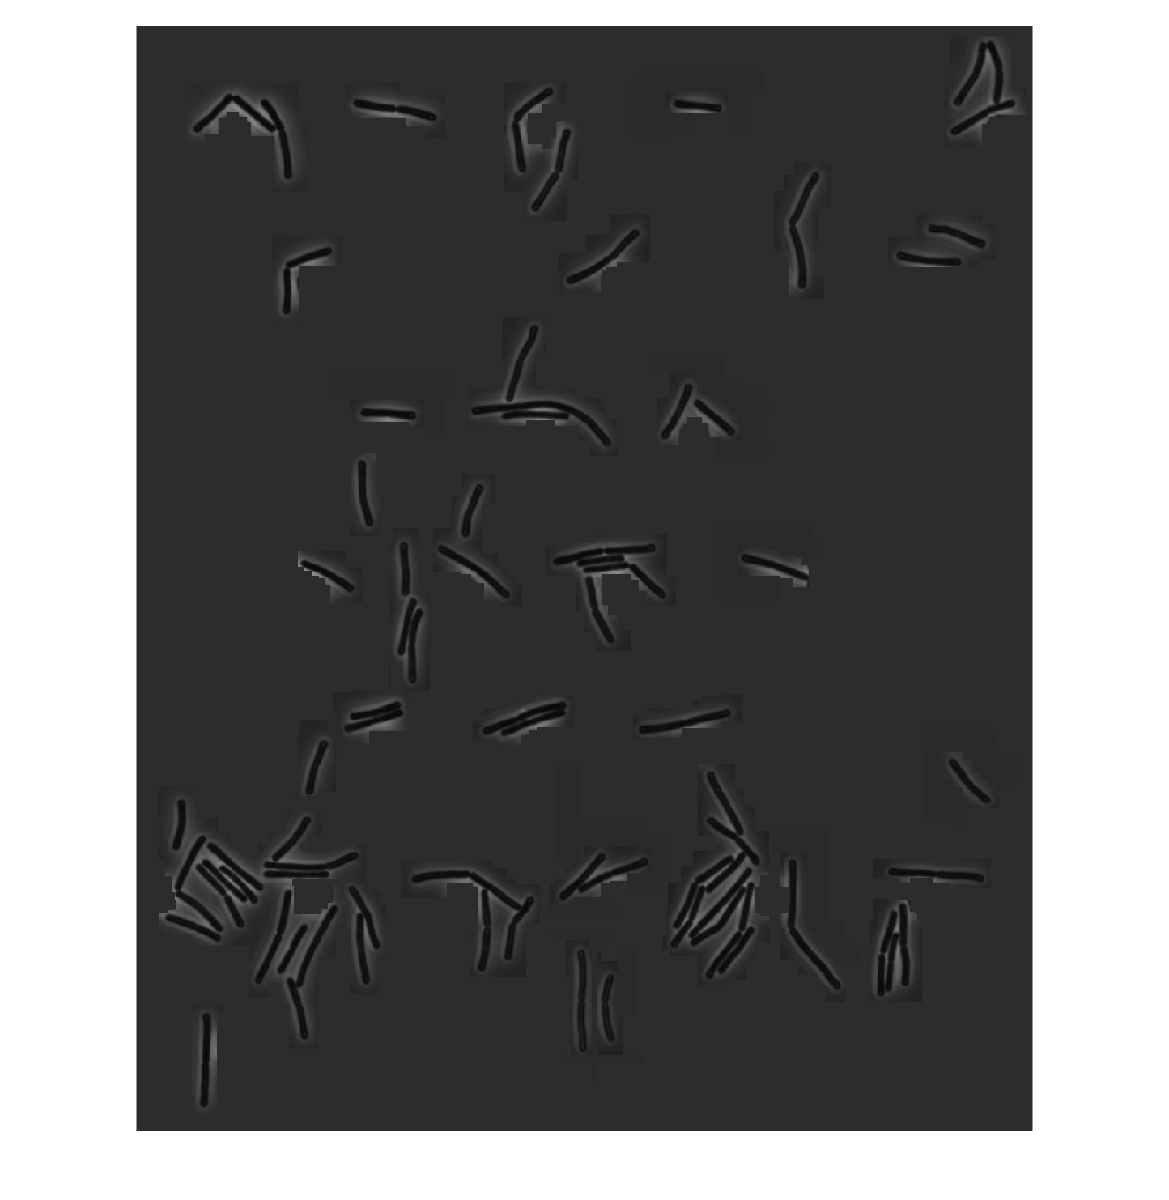

This is what the histogram of the image looks like:

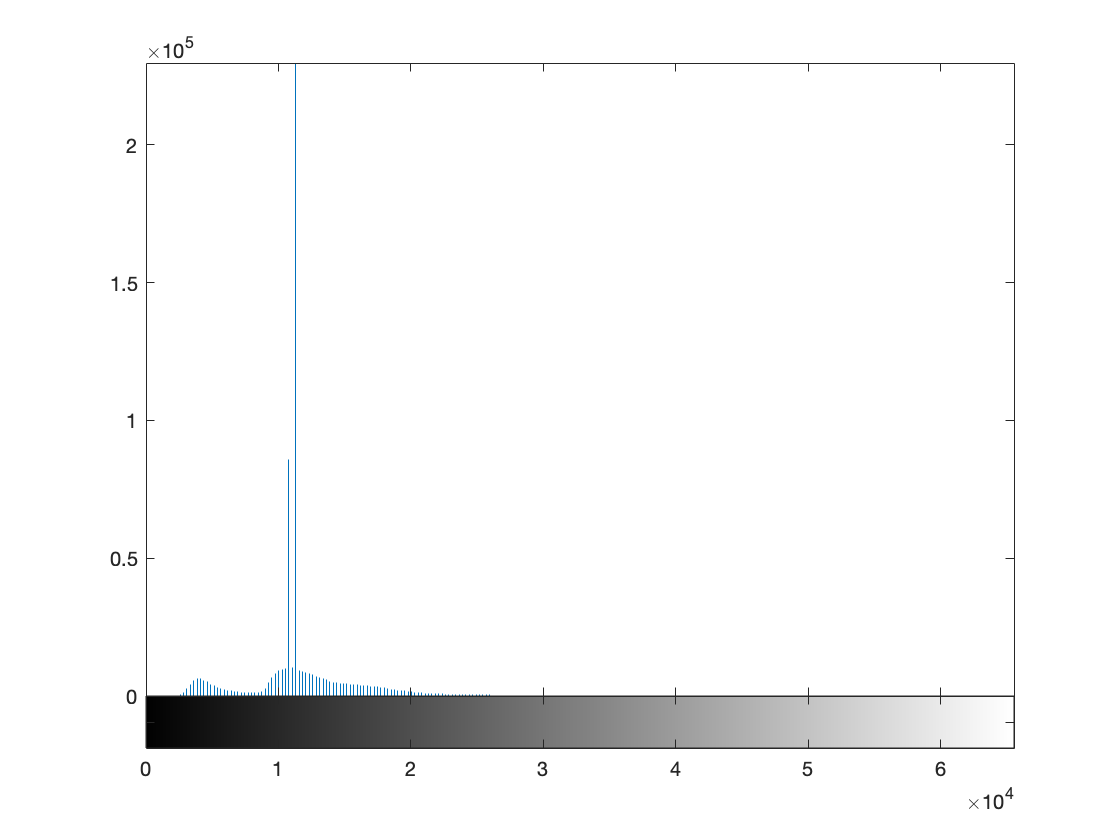

After we read the image, we have to de-speckle it. The function medfilt2 refers to "2-D median filtering" whereby the code looks at each individual pixel and changes its value to match the median value of it's 3-by-3 neighbors. In other words, imagine that the code picks a pixel and then looks to the 3 pixels above it, the 3 pixels below it, and the 3 pixels on either side of it. It looks at the intensity values for those neighboring pixels and calculates a median. That median becomes the new intensity value for your original pixel. Think of this as cleaning the digital debris from your image.

%De-speckle image
im=medfilt2(im);

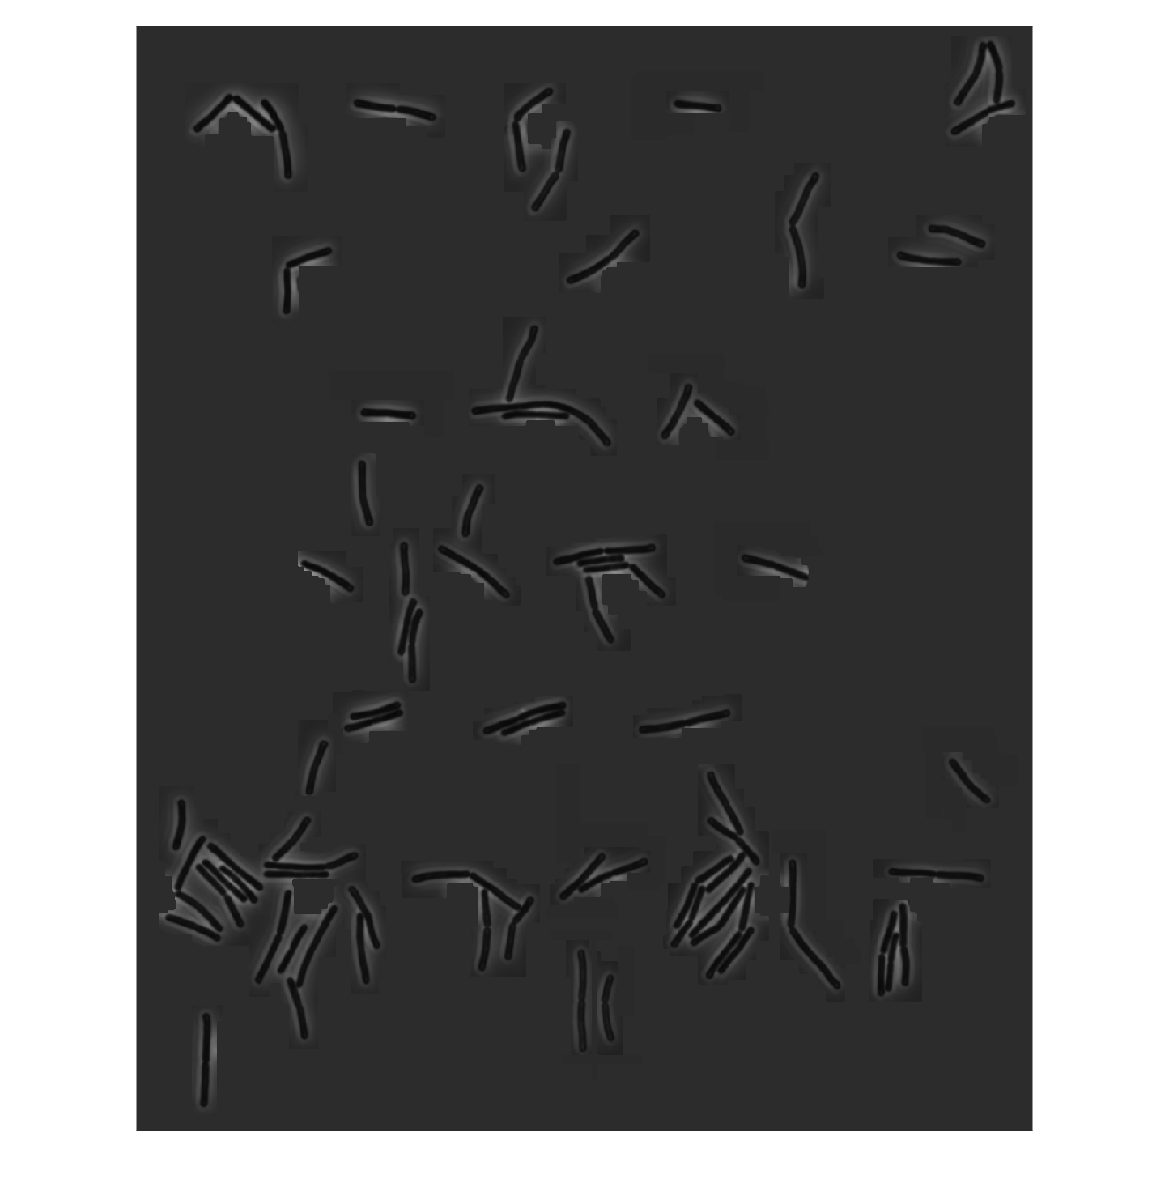

This is what a histogram of the image looks like now:

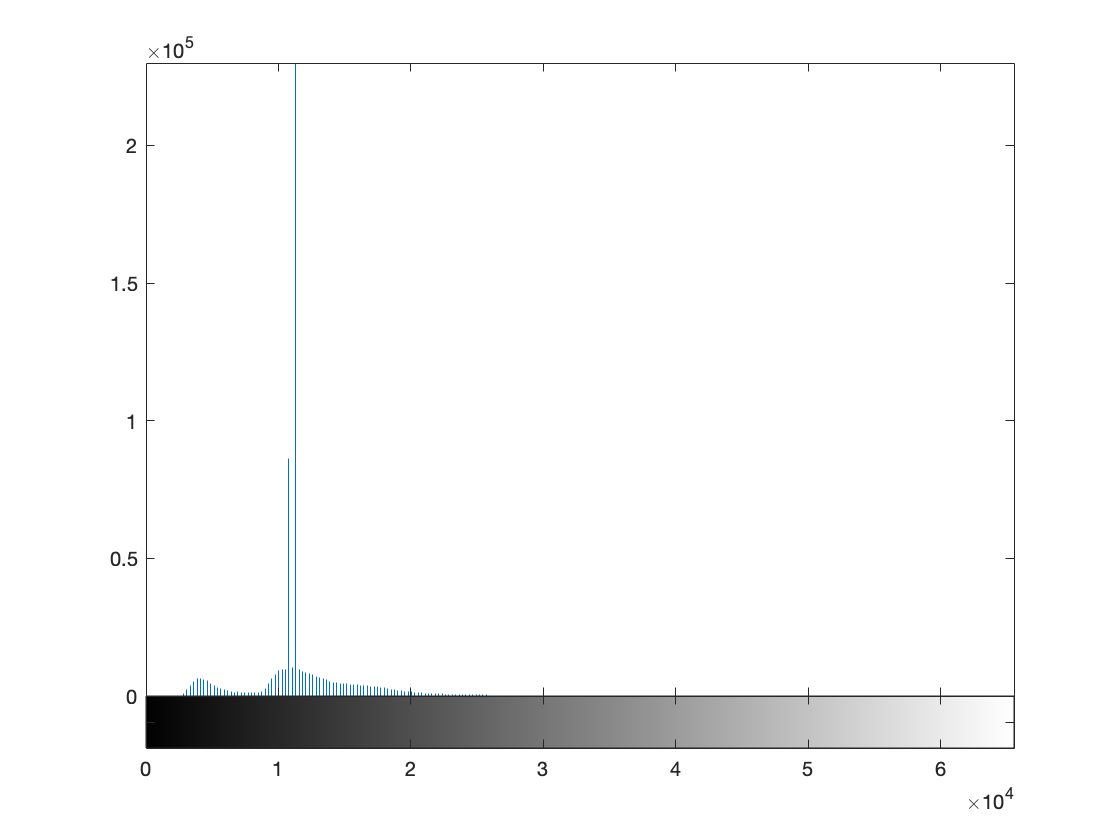

Next, we normalize the image. If you try to find the documentation for the 'norm16bit' function in MATLAB, you will not find it. This function calls the norm16bit.m file. User-defined functions can be written at the end of a script, or they can be stored in a separate script. If they are stored in a separate script, make sure MATLAB can find the path its located in and that the function name and the file name are the same. 

%Normalize images
ppix=0.5;
im=norm16bit(im,ppix);

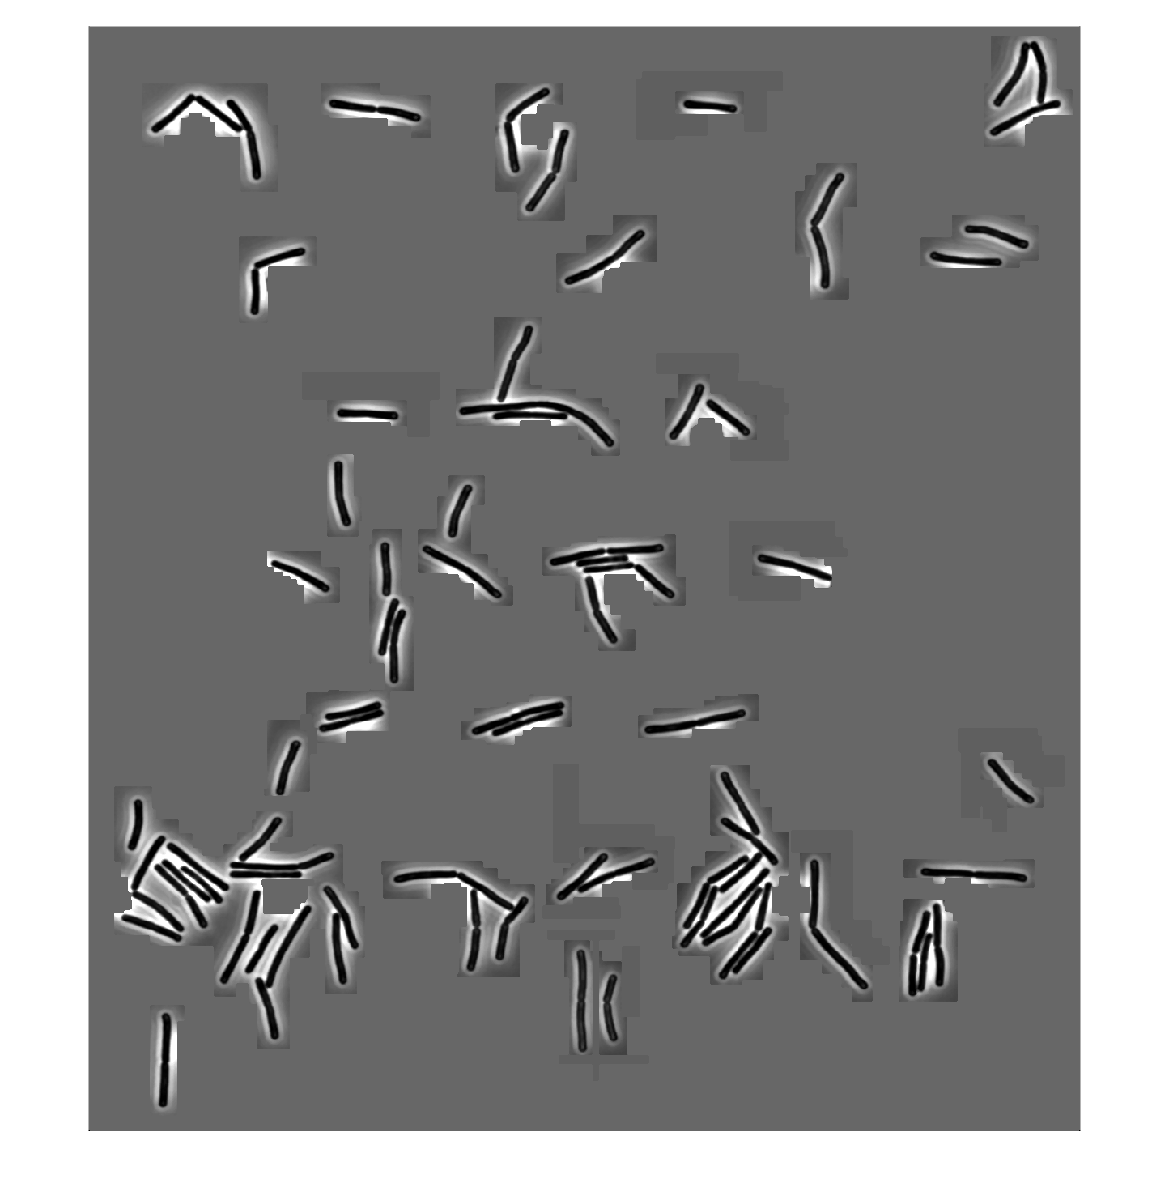

Our image looks brighter than before. What did the norm16bit function do? First, it takes the image and groups the pixel data into pixel intensity (imbin) and the pixel height (imcounts, or amount of pixels at a given intensity). At this point, the cells are the darkest pixels in your image. 

The fliplr function takes the counts array and flips it left-to-right (aka along a vertical axis, so if you had an array 1-2-3 it would be 3-2-1). The output is an array of heights for the pixels from the highest (lightest) to lowest (darkest) pixel intensities. The cumsum function generates an array of cumulative sums, and this output is stored in the csic variable. csci is divided by the total number of pixels and generate an array of proportions, pcsic. You subtract the percentage (in decimal form), take the absolute value and find the index of the minimum. The index corresponds to half of the pixels. You store the index of this minimum value, mpos1. Go back to the imbin variable where your pixel intensities are stored and find the second most abundant pixel intensity; this is the new max intensity value. 

Do the same process on the original imcounts array to find the new max intensity value. You can use the imadjust function to map pixels with values between the new minimum and maximum intensity to values between 0 and 1 (and, by extension, values below the minimum are set to 0 and values above the maximum map to 1). 

%%The following function must be commented out for the script to run
%%properly
% function imout=norm16bit(imin,percent)
% %normalizes the intensity of a 16 bit image, saturating a certain 
% %percentage of the pixels at the max and min values.
% 
% [imcounts,imbin]=hist(double(nonzeros(imin)),1000);
% %figure,plot(imbin,imcounts),pause
% 
% csic=cumsum(fliplr(imcounts));
% pcsic=csic/sum(imcounts);
% [~,mpos1]=min(abs(pcsic-percent/100));
% maxintensity=imbin(end-mpos1);
% 
% csic=cumsum(imcounts);
% pcsic=csic/sum(imcounts');
% [~,mpos2]=min(abs(pcsic-percent/100));
% 
% minintensity=imbin(mpos2);
% 
% imout=imadjust(imin,[minintensity/65535 maxintensity/65535],[]);
% end

This process of normalization is sometimes called histogram stretching. Here might be why:

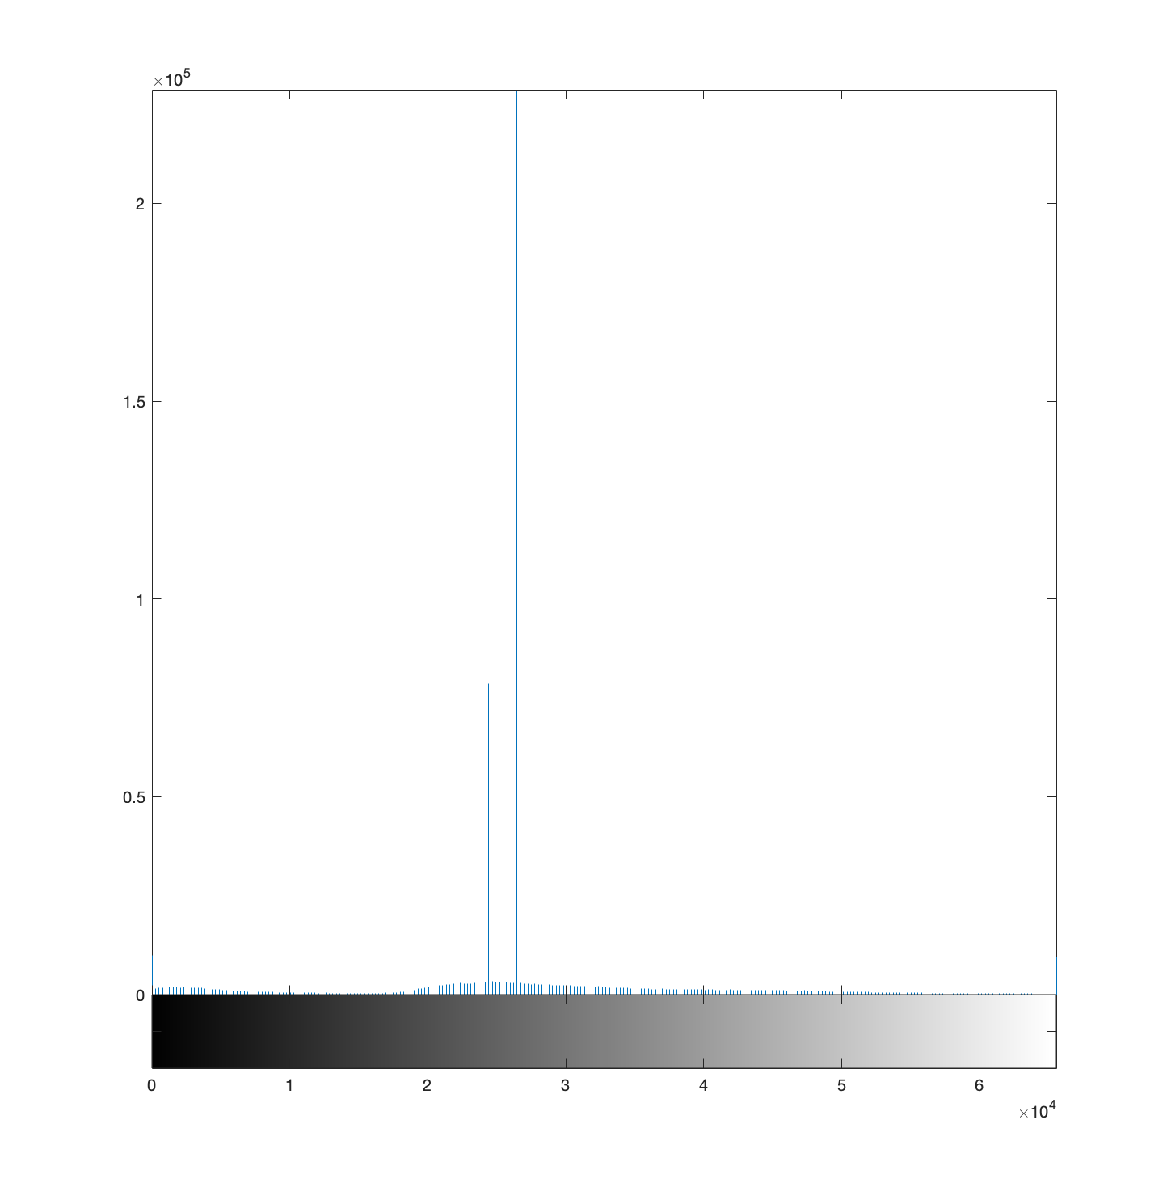

Now that we've normalized the image, let's enhance the contrast. For a binary image, imcomplement turns ones to zeros and zeros to ones. For this grayscale image, the pixel intensities are subtracted from the absolute maximum supported by this image (65535) and the absolute value difference is set as the new pixel intensity. 

imc=imcomplement(im);

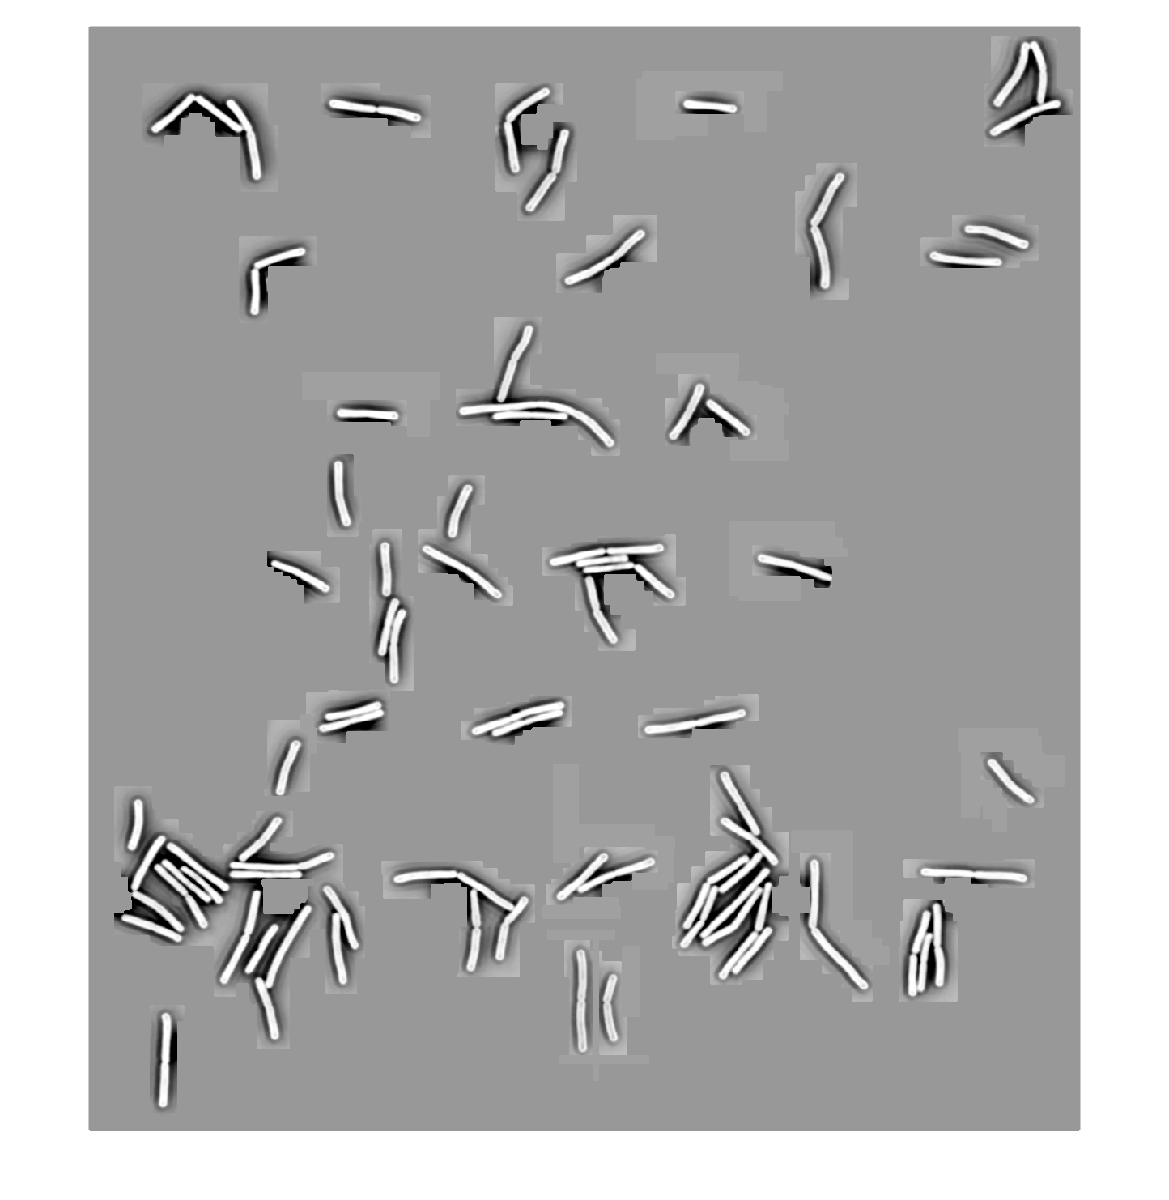

Let's see how the histogram changes. It looks like it was flipped along a vertical axis.

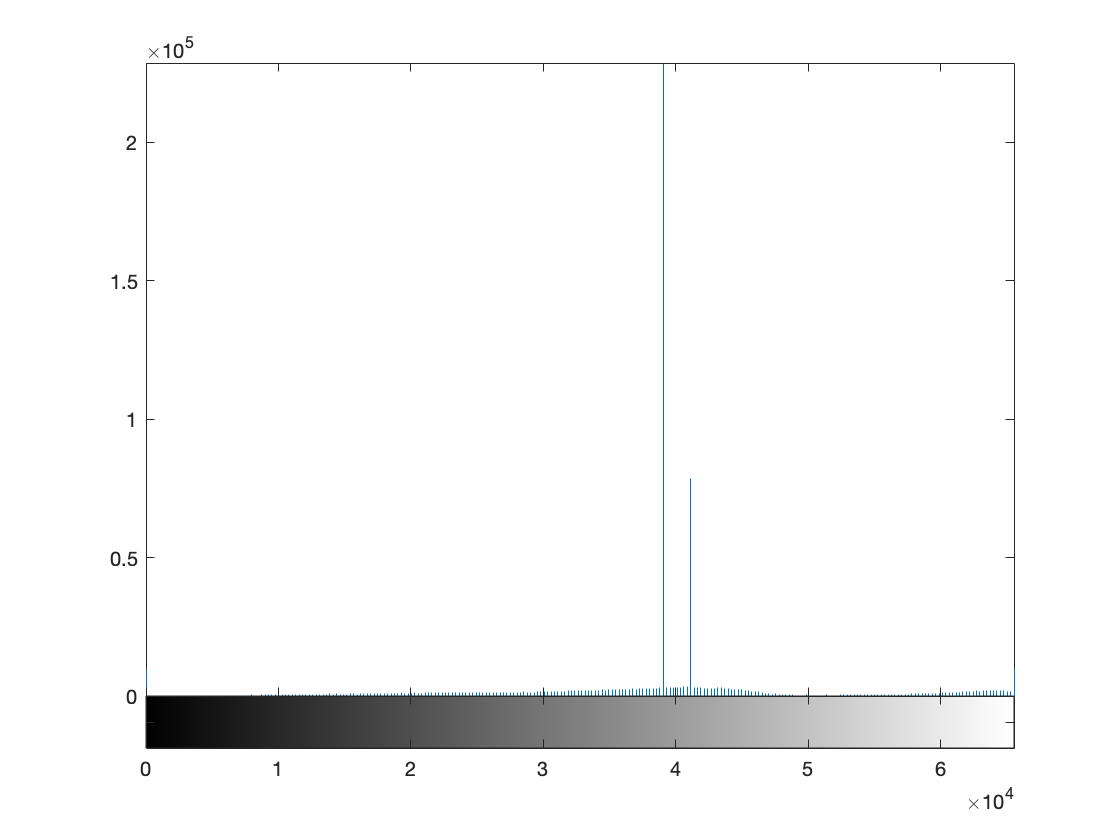

Now for another adjustment. (Remember, by default, thresh==0). If the default is true, then thresh1 equals the pixel intensity of the second highest bin, and thus anything below this value is mapped to 0. 

if thresh==0;
    [imcounts,bins]=imhist(imc);
    [imcounts,idx]=sort(imcounts);
    bins=bins(idx);
    thresh1=bins(end-1);
else
    thresh1=thresh;
end
    imc=imadjust(imc,[thresh1/65535 1],[]);   

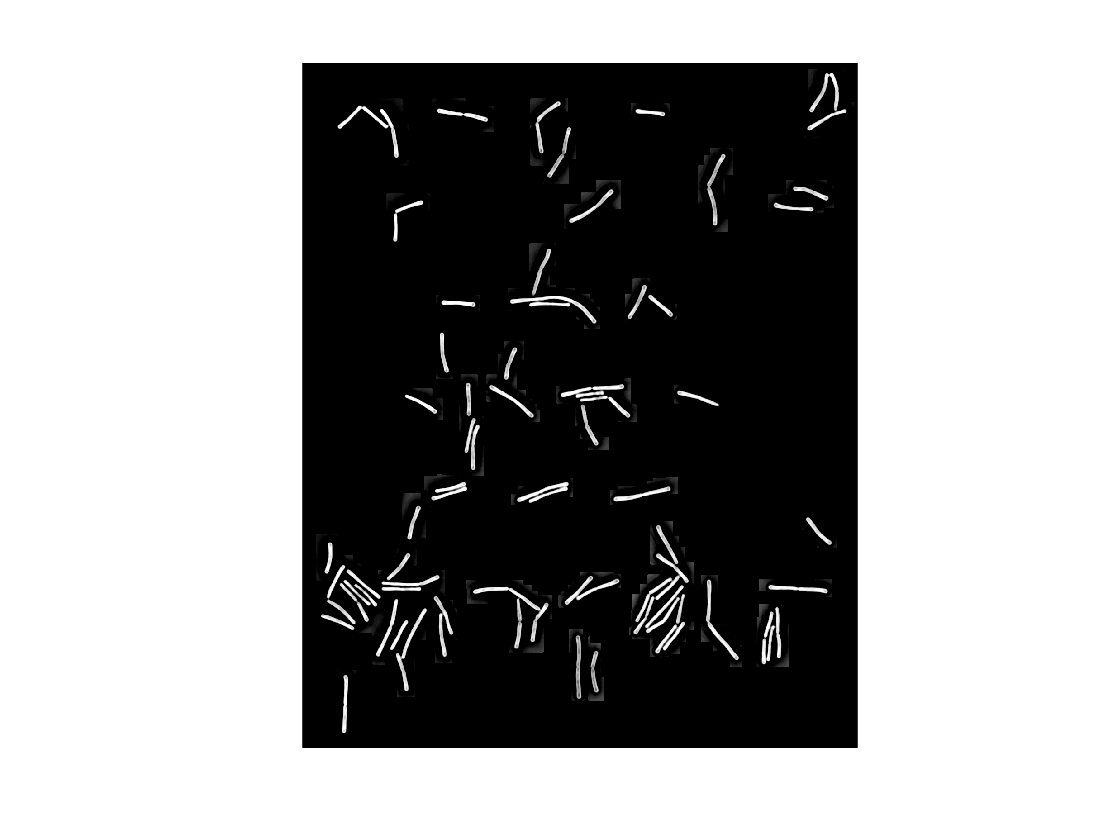

Let's see the histogram.

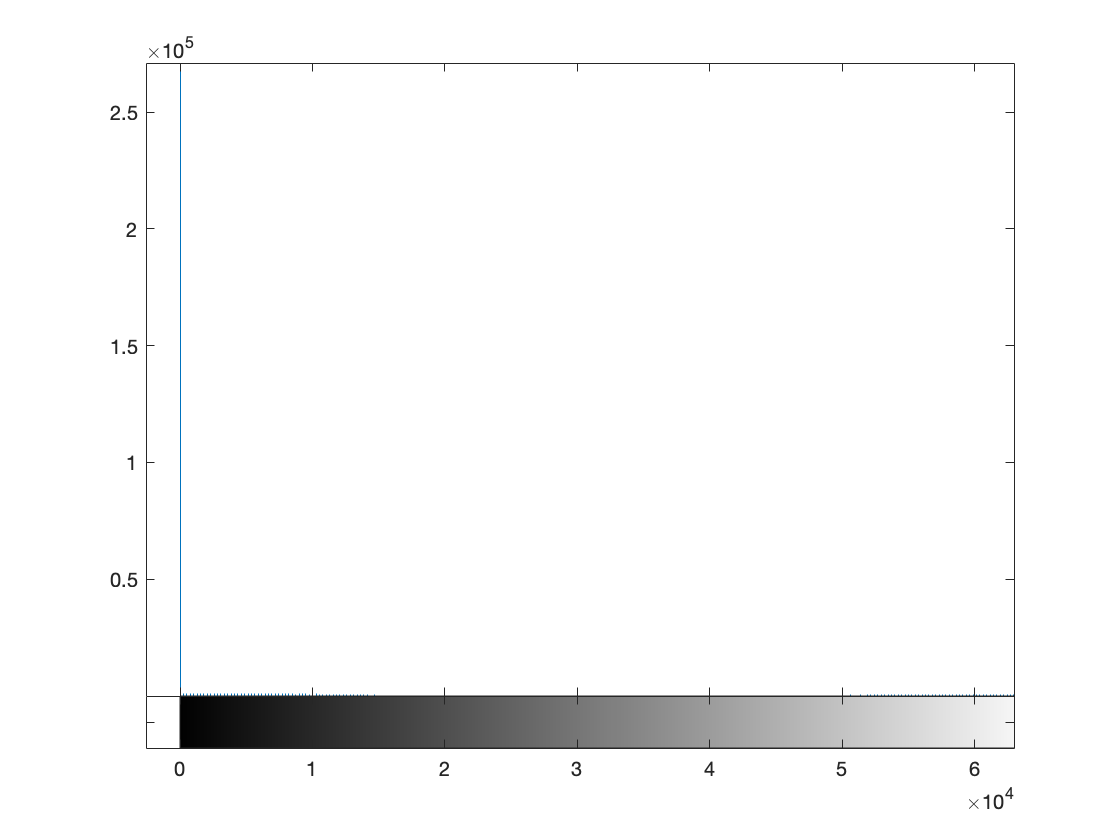

Next, identify edges. The edge() is part of the MATLAB Image Processing Toolbox. The first input is our enhanced, complemented image, where the cells are white and the background is black. The second argument is the method of edge detection, and MATLAB offers seven methods to chose from: 'Sobel', 'Prewitt', 'Roberts', 'log', 'zerocross', 'Canny', and 'approxcanny'. The first three methods find the edges at points where the gradient of the image is maximum and use eponymous approximations to the derivative. The next two, log and zerocross find edges by looking for zero-crossings after applying a filter. The Canny method finds edges by looking for local maxima in a gradient calculated using the derivative of a Gaussian filter. This method uses two filters and is less likely to be fooled by noise. To apply an approximate version of the Canny method (which executes faster but is less precise, use the approxcanny method. 

The third argument is the threshold. In the case of the Canny method, there are two threshold values: low, below which values are disregarded, and high, above which edges are preserved. If no value is specified, the function automatically calculates one. The last argument is sigma, which is the standard deviation of the filter. The default is sqrt(2). We have set sm=2, so our sigma is 2.8284. The output is a binary image where the edges are 1s and non-edges are 0s. The second output, thresh2, is the two-element vector that contains the low and high threshold values used in the canny method. In this case, thresh2=[0.0063 0.0156].

 %Find edges
[ed2,thresh2]=edge(imc,'canny',[],sm*sqrt(2));

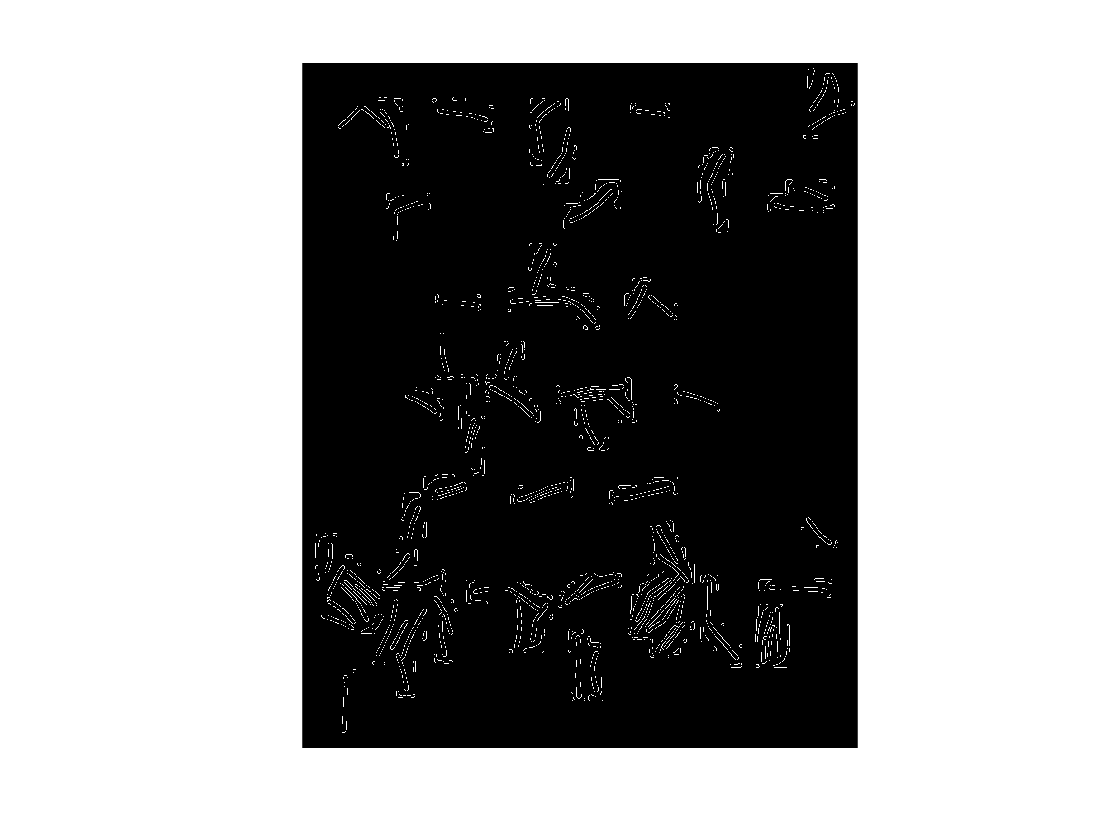

What if we increased sm? How would out edge detection change? If we increase sm to 4, thresh2=[0.0063 0.0156], which is the same as before. However, the outlines of the cells is bigger, as shown in the figure below (sm=2 on the left and sm=4 on the right).

%Find edges
sm=4;
[ed2,thresh2]=edge(imc,'canny',[],sm*sqrt(2));

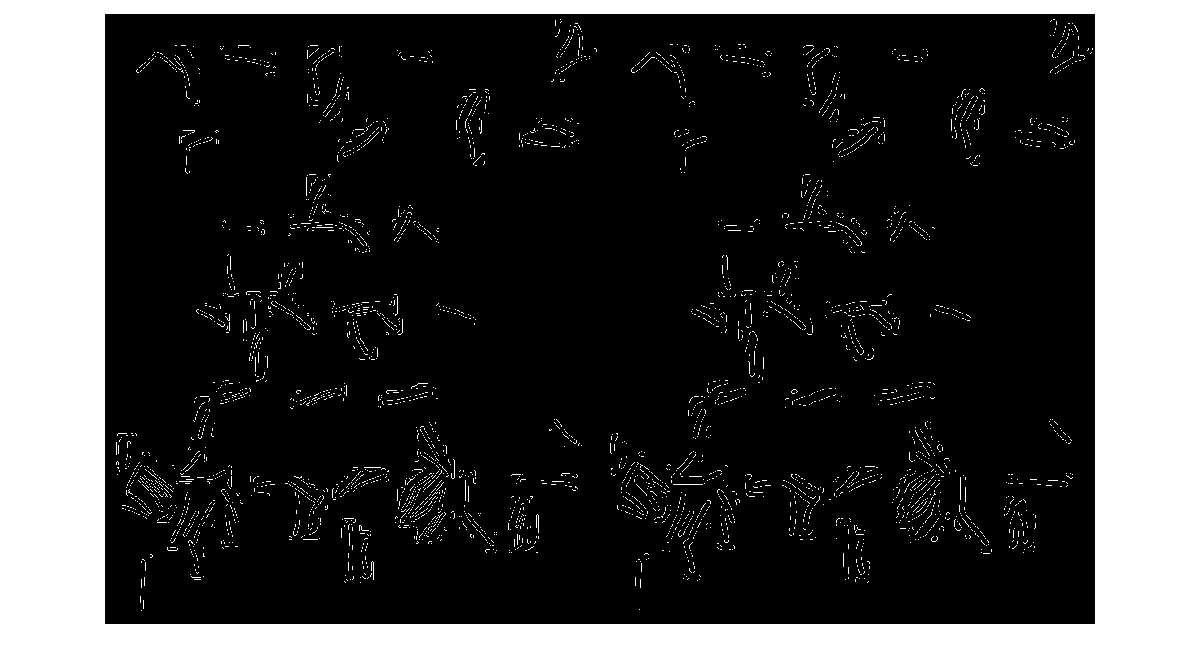

And if we reduce the sm value to sm=1, the threshold values are *still *the same, but the cells identified are thinner and there is more noise, as shown in the figure below (sm=2 on the left and sm=1 on the right). I am not sure why changing the standard deviation of the filter doesn't change threshold values but it does change the identified cell width. 

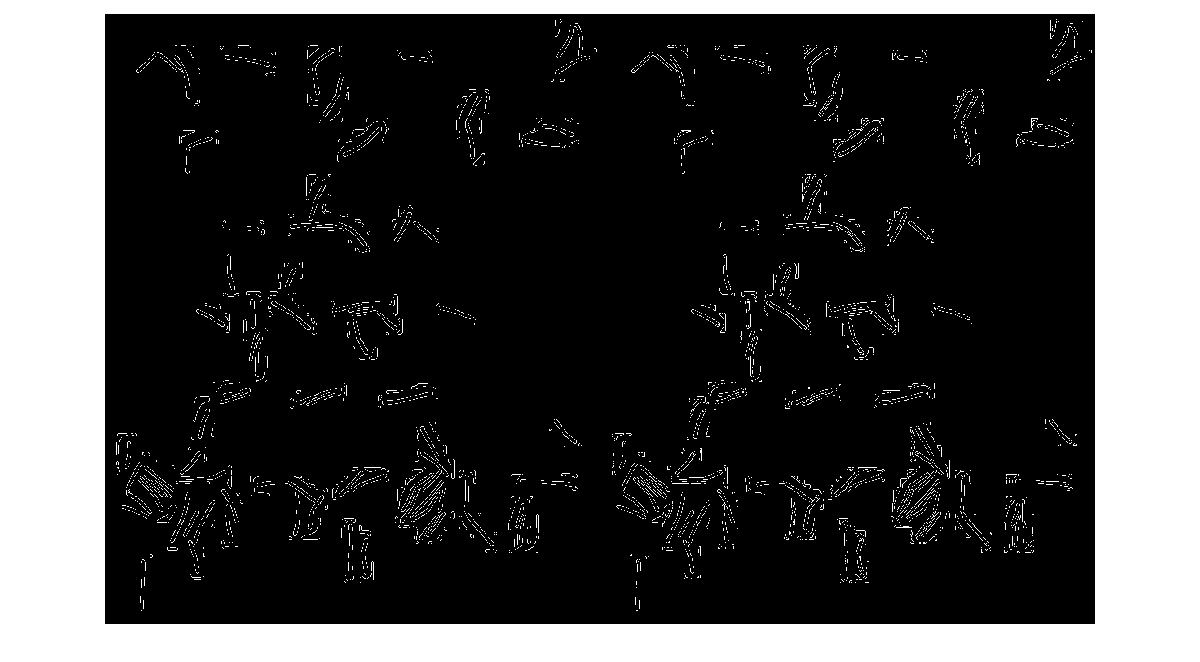

We also need to clean this binary image of all the noise. In the montage below, the contrasted, enhanced 16-bit image is show on the left and the binary image is shown on the right. In some places, it's obvious to see the misdetection, in others it's less clear. One way to fix this is to find the connected components in the binary image 

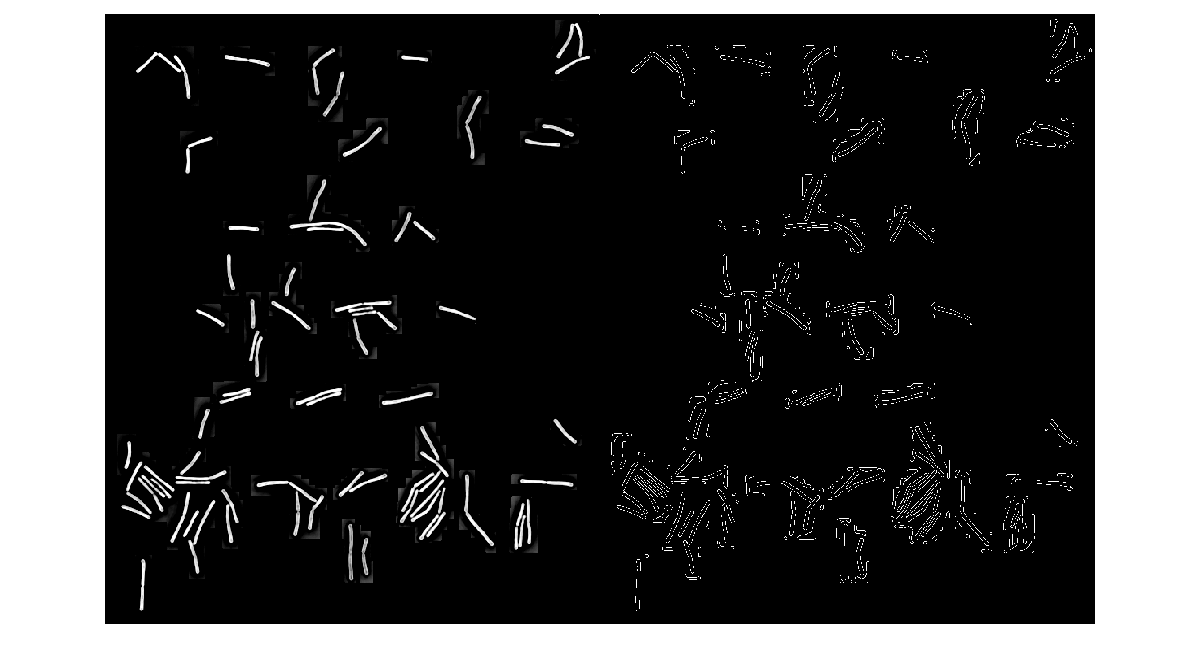

In the first line of the following code, the function bwconncomp finds connected components in a binary image, and the second argument (conn=8) specifies that these connections do not only have to be vertical and horizontal but can be diagonal as well. Hence, the output cc is not an image, but a structure that specifies the image size and a PixelIdxList which is a cell array with matricies that specifiy that pixels in connected components (in this case, the outlined cells). 

%Clean image
cc=bwconncomp(ed2,8);
stats=regionprops(cc,imc,'Area','MeanIntensity');
idx=find([stats.Area]>minA&[stats.Area]<1e5&[stats.MeanIntensity]>IntThresh);
ed2=ismember(labelmatrix(cc),idx);

The second line has the function regionprops, which allows you to quantify image properties, such as area and mean intensity is the specified regions of an image. In this case, the regions are specified by cc. The output , stats, is an array of structures, where each field corresponds to a property and each element of the array corresponds to a region or cell in the PixelIdxList cell array of cc. We can then identify the regions that meet specific area and intensity criteria and store those indexes in the idx matrix. The last line in this block generates a label matrix from cc (a matrix where all the connected componetns are uniquely labeled) and determines whether each labeled component is also a member of the idx array. For example, if 5 is one of the values stored in the index array, then the matrix values in the component labeled '5' in the label matrix correspond to 1 in the output matrix generated by the ismember function. If there is a labeled value in the label matrix that does not correspond to a value in the idx array, then the value corresponds to 0 in the output matrix. On the left is the original ed2 and on the right is the new ed2. It looks much cleaner, but notice that there are still a lot of gaps in our edges.

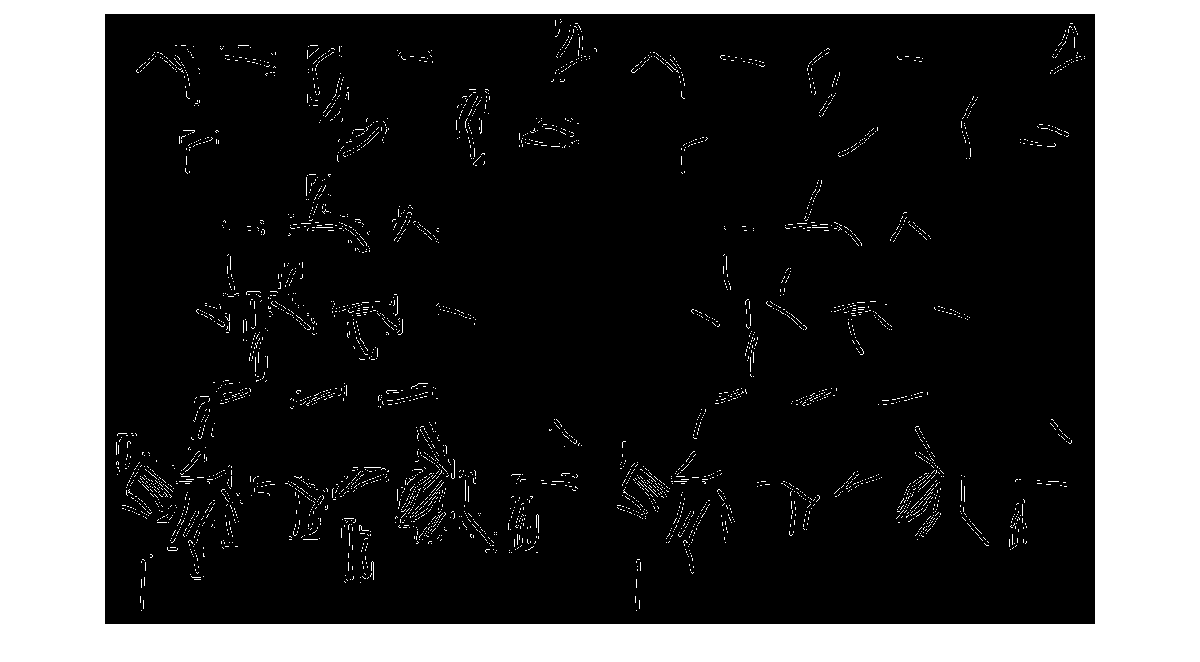

The function bwmorph allows us to perform morphological operations on a binary image, such as ed2. There are 18 operations to chose from so I won't go through all of them right now. But the one used here, spur, literally removes what are referred to as 'spur pixels' or a pixel with a value of 1 that is only connected to one other pixel value equalled to 1. The output is your image without spurs. I can't show the before and after of this because it's actually quite difficult to tell because the difference is at the single-pixel magnitude. 

%Close gaps in edges
despurred=bwmorph(ed2,'spur');
spurs=ed2-despurred;
[spy,spx]=find(spurs); %store the row and col of each nonzero element in the spurs array

The next line is a bit tricky to demonstrate, so first I'll show it as  a comment and then break it down further. 

% for k=1:length(spx)
%     ed2(spy(k)-1:spy(k)+1,spx(k)-1:spx(k)+1)=ed2(spy(k)-1:spy(k)+1,spx(k)-1:spx(k)+1)+rot90(ed2(spy(k)-1:spy(k)+1,spx(k)-1:spx(k)+1),2);
%     ed2(spy(k),spx(k))=1;
% end

%Step 1: pull out the row and column before the spur and the row and column after the spur 
k=1;
v1=ed2(spy(k)-1:spy(k)+1,spx(k)-1:spx(k)+1);
v1

v1 = 3×3 logical array
   0   0   0
   0   1   1
   0   0   0



%Step 2: flip this matrix 180 degrees
v2=rot90(ed2(spy(k)-1:spy(k)+1,spx(k)-1:spx(k)+1),2);
v2

v2 = 3×3 logical array
   0   0   0
   1   1   0
   0   0   0



%Step 3: add them together to close the gap
v1 + v2

ans =      0     0     0
     1     2     1
     0     0     0


%Step 4: make sure that the previous spur value remains 1 (so that the
%image remains binary)
 ed2(spy(k),spx(k))=1;

Let's actually go through the loop.The 'bridge' argument in the bwmorph function is a bit self-explanatory: it "bridges" unconnected pixels. In other words, if a pixel has a value of 0 but is flanked on both sides by 1's, then that pixel value is set to 1. The difference between the images pre- and post-bridging is also at single-pixel resolution, so it's difficult to see unless you zoom in. 

for k=1:length(spx)
    ed2(spy(k)-1:spy(k)+1,spx(k)-1:spx(k)+1)=ed2(spy(k)-1:spy(k)+1,spx(k)-1:spx(k)+1)+rot90(ed2(spy(k)-1:spy(k)+1,spx(k)-1:spx(k)+1),2);
    ed2(spy(k),spx(k))=1;
end

ed2=bwmorph(ed2,'bridge'); 

The strel function represents a flat morphological object (in this case, a disk with radius dr=1). The radius refers to the distance from the origin to the edge of the disk. 

se=strel('disk',dr)

se = strel is a disk shaped structuring element with properties:

      Neighborhood: [3×3 logical]
    Dimensionality: 2


se.Neighborhood
se.Dimensionality
ed2=imdilate(ed2,se);
ed2=bwmorph(ed2,'thin',2);

On the left, you can see the undilated image and on the right the dialted image. Dilation adds pixels to the boundary of an object, and the number of pixels added are based on the size and shape of the structuring element. 

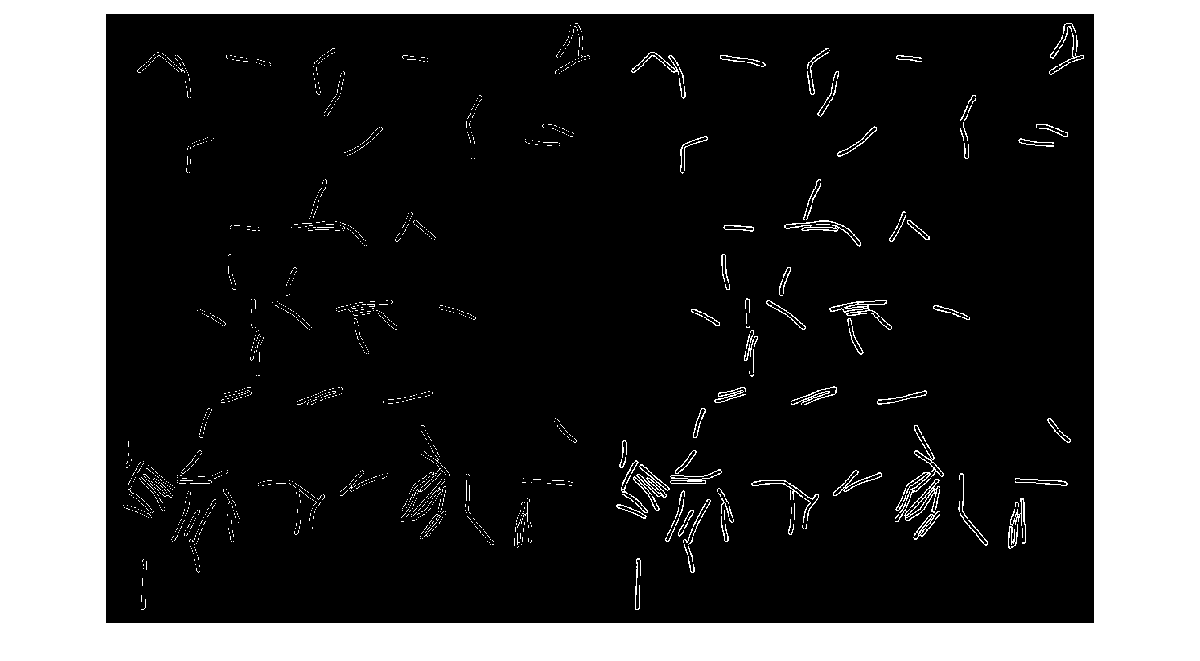

The 'thin' option subsequently removes pixels, as shown on the right (the dilated image shown on the left).

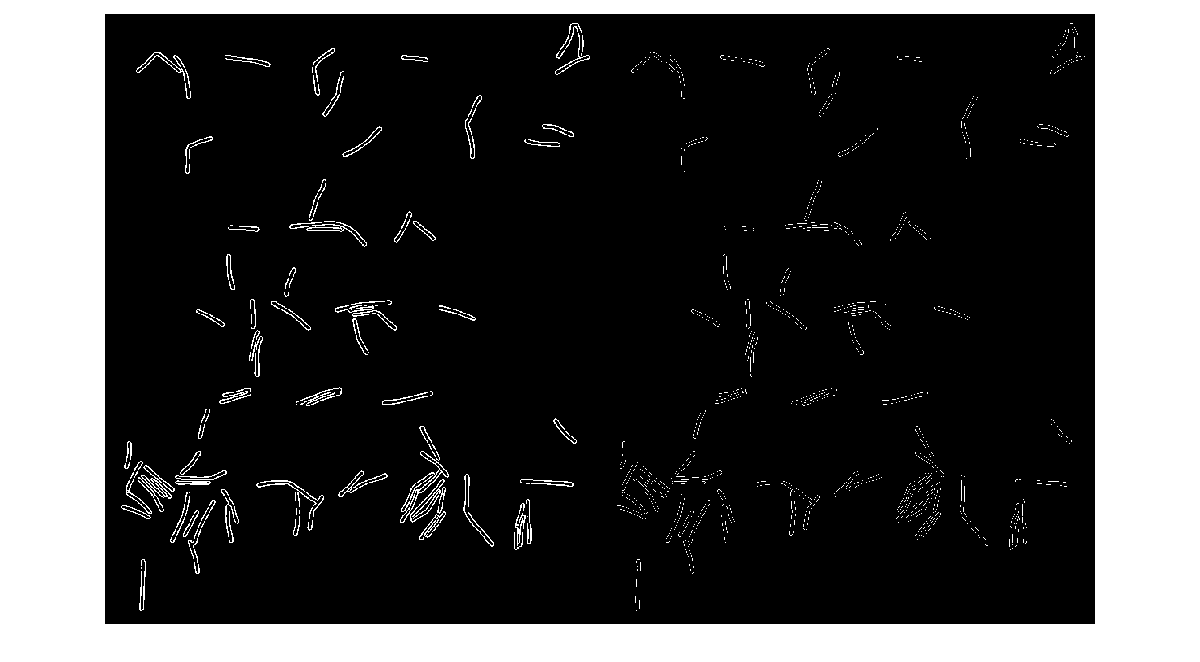

Now, let's identify cells based on size and intensity. First, let's flip the matrix from black-and-white to white-and-black by creating a new matrix where all the 1's get changed to 0's and all the 0's get changed to 1's. In addition, make sure that all the pixels in the first row , first column, last row, and last column of the matrix (the edges of the image) have values of 1 so that cells at the edges are not counted. 

We identify connected components again, this time with 4-pixel connectivity instead of 8 (if you change the connectivity to 8, you wouldn't identify any cells, and while I'm not entirely sure why, I assume it's because after all our processing the outlines of the cell boundaries have a single-pixel width). And I'm not sure where the intensity and area cutoffs are derived from either. The image gets flipped back to black-and-white because, remember, the output of ismember is a logical array whereby all the pixels within the components that meet the criteria are set to 1 and everything else is set to 0. On the left is the image of ed3 and on the right is ed4.

%Identify cells based on size and intensity
ed3=~ed2;
ed3(1,:)=ones(1,imN);
ed3(end,:)=ones(1,imN);
ed3(:,1)=ones(imM,1);
ed3(:,end)=ones(imM,1);

cc=bwconncomp(ed3,4);
stats=regionprops(cc,imc,'Area','MeanIntensity');
idx=find([stats.Area]>minA&[stats.Area]<1e5&[stats.MeanIntensity]>3e4);
ed4=ismember(labelmatrix(cc),idx);

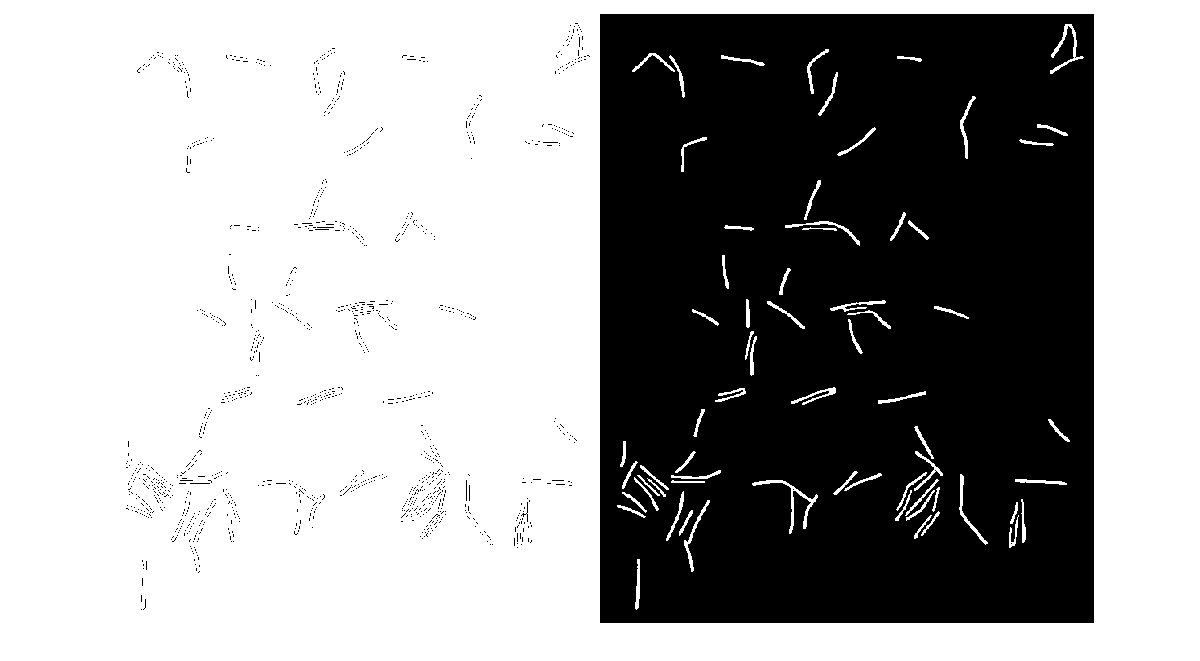

Next, we use the bwmorph function to thicken the boundary by adding pixels until previously unconnected objects are 8-connected. According to the documentation, the third option "[specifies] whether you want to include the boundaries of holes inside other objects." In other words, do you also take the coordinates of the holes? Here, it specifies we do not. The output P, a cell array of coordinates for each cell, and bw is a label matrix. The output bw is a label matrix. You can then determine the area, centroid, and pixel ID (liner indicies) of those labeled objects. The image below shows imshow(bw).

%Find cell areas and centroids
bw=bwmorph(ed4,'thicken');
[P,bw]=bwboundaries(bw,4,'noholes');
stats=regionprops(bw,'Area','Centroid','PixelIdxList');

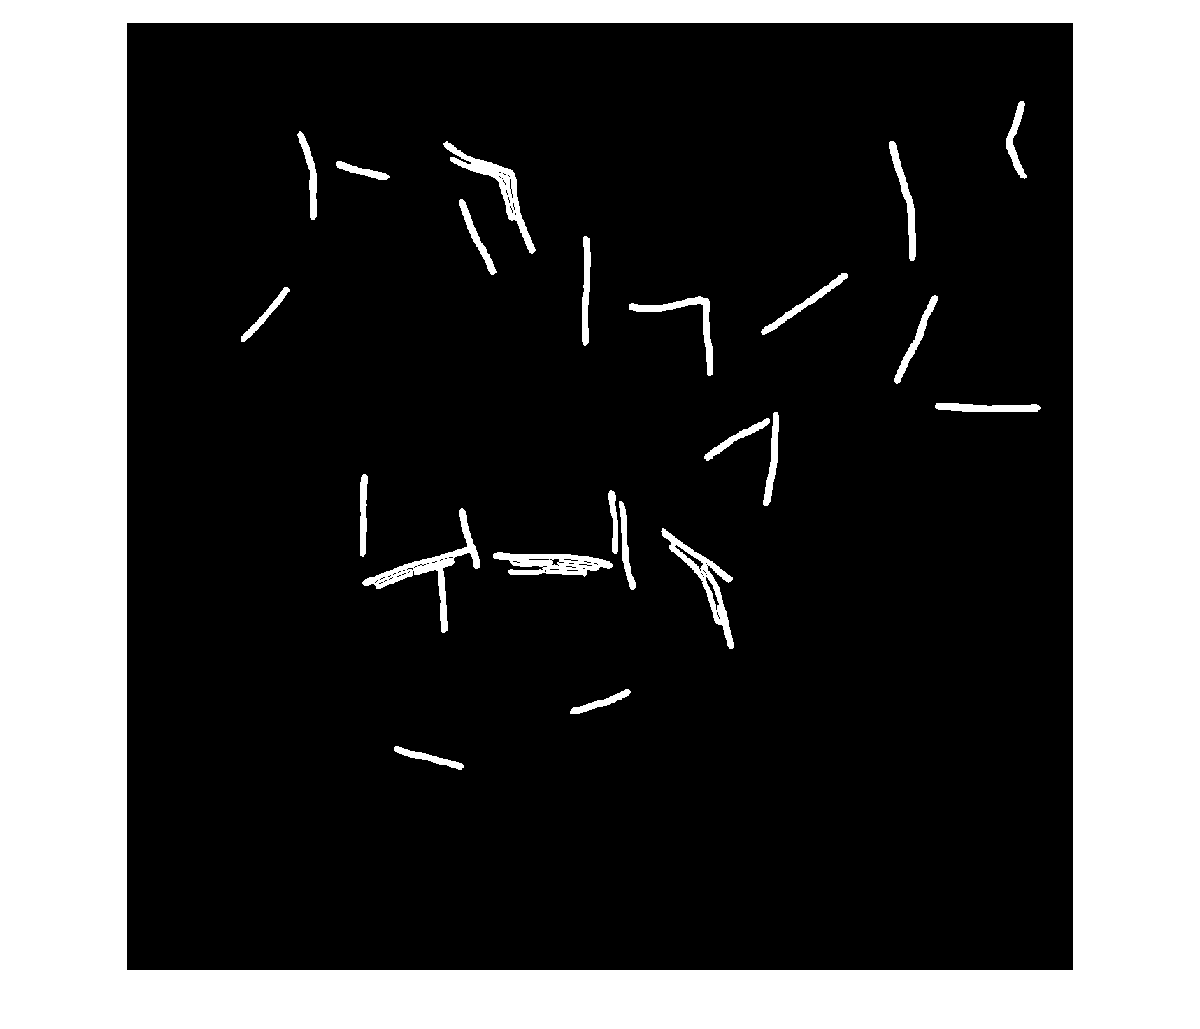

The first line below returns a label matrix of connected components, although this I find redundant since bw is already a label matrix. There label matricies are stored for each time point into a 3D cell array, which will then be stored in a .mat file.

 L=bwlabel(bw);    
labels(:,:,t)=L;
labels2(:,:,t)=bw;

Remember that the variable P is a cell array, in which each cell contains the row x column components of each cell. Using the regionprops function, we had already calculated the area and centroid values for each cell, and we use those values to pre-allocate other variables.

nc(t)=length(P);
areas=[stats.Area];
cents=cat(1,stats.Centroid);
a(nc(t),t)=0;
a(1:nc(t),t)=[stats.Area]'; 
centroids=cents;

Now, for the fun part. Calculating smooth cell contours. This runs as a loop through all cells, but for our purposes, we'll take a closer look at the first cell. First, we look at the cell that contains the coordinates for our first object and reverse the order of the columns (col1=rows=y, col2=columns=x). The next two lines a don't understand: you essentially combine the arrays by row two times. And then, after storing the number of coordinate in the original object, you find the difference of each element in the px and py matrix along the first dimension greater than 1. You end up with a vertical array of 1's, 0's, and -1's, which you then square to remove the negatives.Then, you add these square differences of px and py and find the square root of the sum. Basically, this is the normalized Euclidean distance between each point in the object (I think?). The csaps function calulates the cubic smoothing spline and returns it as an array. (Question!: I'm still not entirely sure how this part of the algorightm works, or that I could explain it, but I figure that it uses splines to calculate the contours, and splines are like "in-between" points, a bunch of points and lines that look like a curve if you zoom out).

%Calculate smooth cell contours
for n=1:%nc(t)
     
    rP=[P{n}(:,2),P{n}(:,1)];
    px=[rP(1:end-1,1);rP(1:end-1,1);rP(:,1)];
    py=[rP(1:end-1,2);rP(1:end-1,2);rP(:,2)];
    sp=length(rP);
    dS=sqrt(diff(px).^2+diff(py).^2);
    S=[0 cumsum(dS)'];

    px=csaps(S,px,0.05,S);
    py=csaps(S,py,0.05,S);
    
    px=px(sp+1:2*sp);
    py=py(sp+1:2*sp);
    
    px(end)=px(1);
    py(end)=py(1);
    
    dS=sqrt(diff(px).^2+diff(py).^2);
    S=[0 cumsum(dS)];
    ls=length(S);
    DS(n,t)=S(end)/(ls-1);
    Sn=(0:DS(n,t):S(end));
    nx=spline(S,px,Sn);
    ny=spline(S,py,Sn);
    
    boun{n,t}=[nx',ny'];
    pxls{n,t}=stats(n).PixelIdxList;
    
end

allcentroids=[allcentroids;centroids];
tstamp=[tstamp;ones(nc(t),1)*t];
cellnum=[cellnum;(1:nc(t))'];

We are getting to the end of the time for loop. The final step is to visual our new cell line boundaries on our image.

if vis==1 & t >= T-10 | t <= 6
    figure
    imshow(im)
    hold on
    for k=1:nc(t)
       plot(boun{k,t}(:,1),boun{k,t}(:,2),'-r')
    end
end

We've finally ended our loop. Now, let's get to the calculations. Again, we are just going to be looking at the first cell in the first frame. For each cell, get the x and y values of the boun variable (which has the spline coordinates). 

%Calculate cell length, width, etc.
% for t=1
t=1;
% for n=1:nc(t)   
n=1;
         X=boun{n,t}(:,1);
         Y=boun{n,t}(:,2);   
                       
         [sX,~]=size(X);
         
         %Find poles
         [X,Y,pole(n,t)]=polefinder(X,Y);
         

How do we find the poles? The polefinder function is defined below....

%          function [X,Y,pole]=polefinder(X,Y);
% 
%          K=cellcurvature(X,Y,1);

....and immediately it's a function within a function. As the name suggests, it calculates the curvature of a cell contour (Question! how does it actually do this???)

%K=cellcurvature(X,Y,neighbor)
%This program calculates the curvature of a cell contour and averages over
%the neighboring points.
%
%INPUT
%X,Y: x and y coordinates of cell boundaries.
%neighbor: number of points to average curvature over.
% 
% function K=cellcurvature(X,Y,neighbor)
% 
%          [sX,temp]=size(X);
% 
%          dX=diff(X);
%          dY=diff(Y);
%          
%          dS=sqrt(dX.^2+dY.^2);
%          S=[0 cumsum(dS)'];
%          DS=S(end)/(sX-1);
%          
%          NNx=zeros(sX-1,1);
%          NNy=zeros(sX-1,1);
%          
%          NNx=dY./DS;
%          NNy=-dX./DS;
%          NN3=[NNx,NNy,zeros(sX-1,1)];
%          
%          Nlen=sqrt(NNx.^2+NNy.^2);
%          
%          Ndot=NNx(1:end-1).*NNx(2:end)+NNy(1:end-1).*NNy(2:end);
%          Ncross=cross(NN3(1:end-1,:),NN3(2:end,:));
%          dphi=acos(Ndot./(Nlen(1:end-1).*Nlen(2:end))).*sign(Ncross(:,3));
%          
%          K=zeros(sX,1);
%          K(2:end-1)=dphi/DS;
%          
%          K=smooth(K,neighbor,'moving');

Once you calculate K, the rest of this function calculates the poles (Question! how???), as well as new coordinates for X and Y. Note, the circshift function shifts an array circularly. If other words, imagine your array is a series of numbers on a wheel. You move the wheel 3 positions counter-clockwise. All the same numbers are there, but all the elements have had their positions shifted by 3. 

%          lK=length(K);
% 
%          sigma=15;
%          b=3;
%          win=50;
%          testx=[-win/2:win/2];
%          test=b*exp(-testx.^2/2/(sigma/2).^2);
%          cK=conv([K;K;K],test,'same');
%          
%          [kmax,imax]=extrema(cK);
%          tkmax=imax>lK & imax<=2*lK;
%          imax=imax(tkmax);
%          
%          if length(imax)>1
%             poles=imax(1:2)';
%          else
%             poles(1)=mod(imax(1),lK)+1;
%             poles(2)=mod(poles(1)+round(lK/2),lK)+1;
%          end
%          mpole=min(poles);
%          poles=poles-mpole+1;
%          pole=max(poles);
%          
%          X=circshift(X(1:end-1),-mpole);
%          Y=circshift(Y(1:end-1),-mpole);
%          X=[X;X(1)];
%          Y=[Y;Y(1)];

Back to the loop. Okay, so the function creates a mesh, calculates the midline and calculates the width....still not sure how this happens. (Question! ????)

         
         %Create mesh
         npts=min(pole(n,t),sX-pole(n,t)+1);
         S=(0:DS(n,t):(sX-1)*DS(n,t));
         
         s1=(0:S(pole(n,t))/(npts-1):S(pole(n,t)));
         s2=(S(pole(n,t)):(S(end)-S(pole(n,t)))/(npts-1):S(end));
         xc1=spline(S(1:pole(n,t)),X(1:pole(n,t)),s1);
         xc2=spline(S(pole(n,t):end),X(pole(n,t):end),s2);
         yc1=spline(S(1:pole(n,t)),Y(1:pole(n,t)),s1);
         yc2=spline(S(pole(n,t):end),Y(pole(n,t):end),s2);
         xc2=fliplr(xc2);
         yc2=fliplr(yc2);
         
         %Calculate midline
         mline{n,t}=[(xc1+xc2)'/2,(yc1+yc2)'/2];
         dxy=diff(mline{n,t}).^2;
         dl=sqrt(dxy(:,1)+dxy(:,2));
         l(n,t)=sum(dl);
         
         %Calculate width
         ls=[0 cumsum(dl)'];
         [~,mpos1]=min(abs(ls/l(n,t)-0.25));
         [~,mpos2]=min(abs(ls/l(n,t)-0.75));
         
         widths=sqrt((xc1-xc2).^2+(yc1-yc2).^2);
         w(n,t)=(widths(mpos1)+widths(mpos2))/2;
          
    end

Now, calculate the time points. Since I don't have the metadata, most of this code isn't necessary to know, but the multiScale if statement was added by me since I use multiple time settings in one movie. 

    %Extract timepoints from metadata if it exists
if exist('metaname')==1
    if exist(metaname)==2
        %Extract timepoints from metadata
        tpoints=metadata(metaname);
        
        %Fix bug where micromanager screws up its timing
        dtime=diff(tpoints(1,:));
        fdt=find(dtime>2*(dtime(1)));
        if isempty(fdt)~=1
            fdt=fdt(1);
            tpoints(:,fdt+1:end)=tpoints(:,fdt+1:end)-tpoints(1,fdt+1)+tpoints(1,fdt)+(tpoints(1,fdt)-tpoints(1,fdt-1));
        end
    else
        tpoints=[0:T-1]*tscale;
    end
else
     if multiScale==0
     tpoints=[0:T-1]*tscale;
    elseif multiScale==1
     tpoint1=[0:tscale:tpt1];
     tpoint2=[tpt1+tscale2:tscale2:tpt2];
     tpoint3=[tpt2+tscale:tscale:tpt3];
     tlength=length(tpoint1)+length(tpoint2)+length(tpoint3);
     tpoint4=[tpt3+tscale2:tscale2:tpt4];
     tpoints=[tpoint1, tpoint2, tpoint3, tpoint4];
     tpoints=tpoints(1:T);
    end
end

time=tpoints(1,:);
time2=tpoints(end,:);

%Fix bug where micromanager screws up its timing
dtime=diff(time);
fdt=find(dtime>2*(dtime(1)));
if isempty(fdt)~=1
    fdt=fdt(1);
    time(fdt+1:end)=time(fdt+1:end)-dtime(fdt)+dtime(fdt-1);
    time2(fdt+1:end)=time2(fdt+1:end)-dtime(fdt)+dtime(fdt-1);
end

This is where the cell tracking begins. The variable tracks is a matrix of zeros with the same dimensions as the image. rcents is an integer array of the centroid coordinates (which are x by y, aka column by row). The sub2ind function takes subscripts (row, col coordinates) and returns the corresponding linear indicies of those coordinates in the matrix provided in the first argument. In the track matrix, the position at which the centroid is gets converted to a 1. The following is imshow(tracks), which, if you look closely, has scattered white dots across the black background. Whoops! This is a different image stack. 

%Track cells frame to frame
tracks=zeros(size(im));
rcents=round(allcentroids);
linind=sub2ind(size(im),rcents(:,2),rcents(:,1));
tracks(linind)=1;

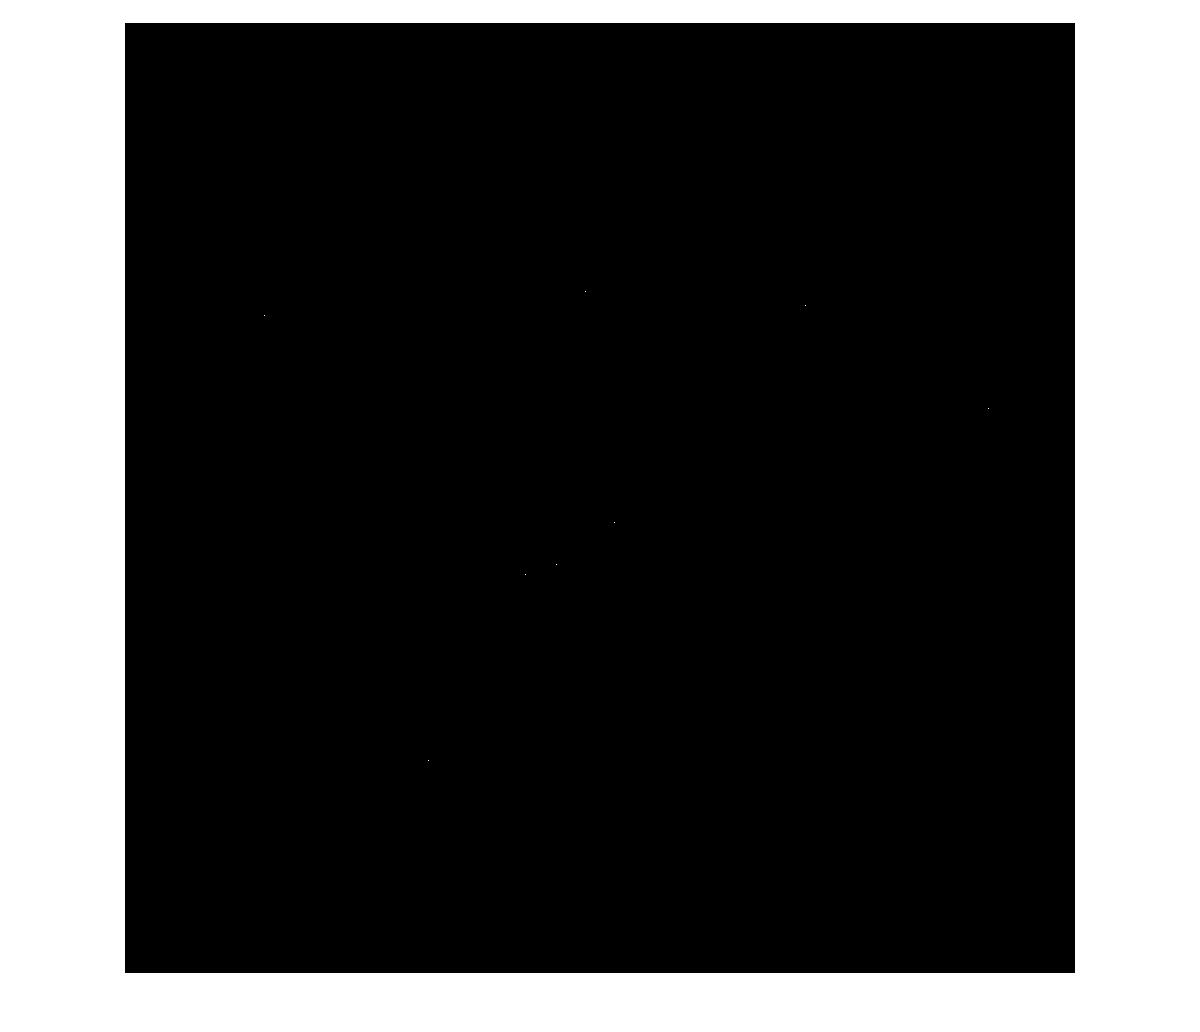

There points are then dilated using the imdilate function, and I'm not entired sure what cellLink does, but I think it's the radius since increasing cellLink increases the size or the circles while decreased cellLink results in small circles.The imoverlay function does exactly what it sounds like it does: it overlays tracks onto im, as shown below.

nhood=[0,1,0;1,1,1;0,1,0];
tracks=imdilate(tracks,strel('disk',cellLink));
overlay1=imoverlay(im,tracks,[.3 1 .3]);

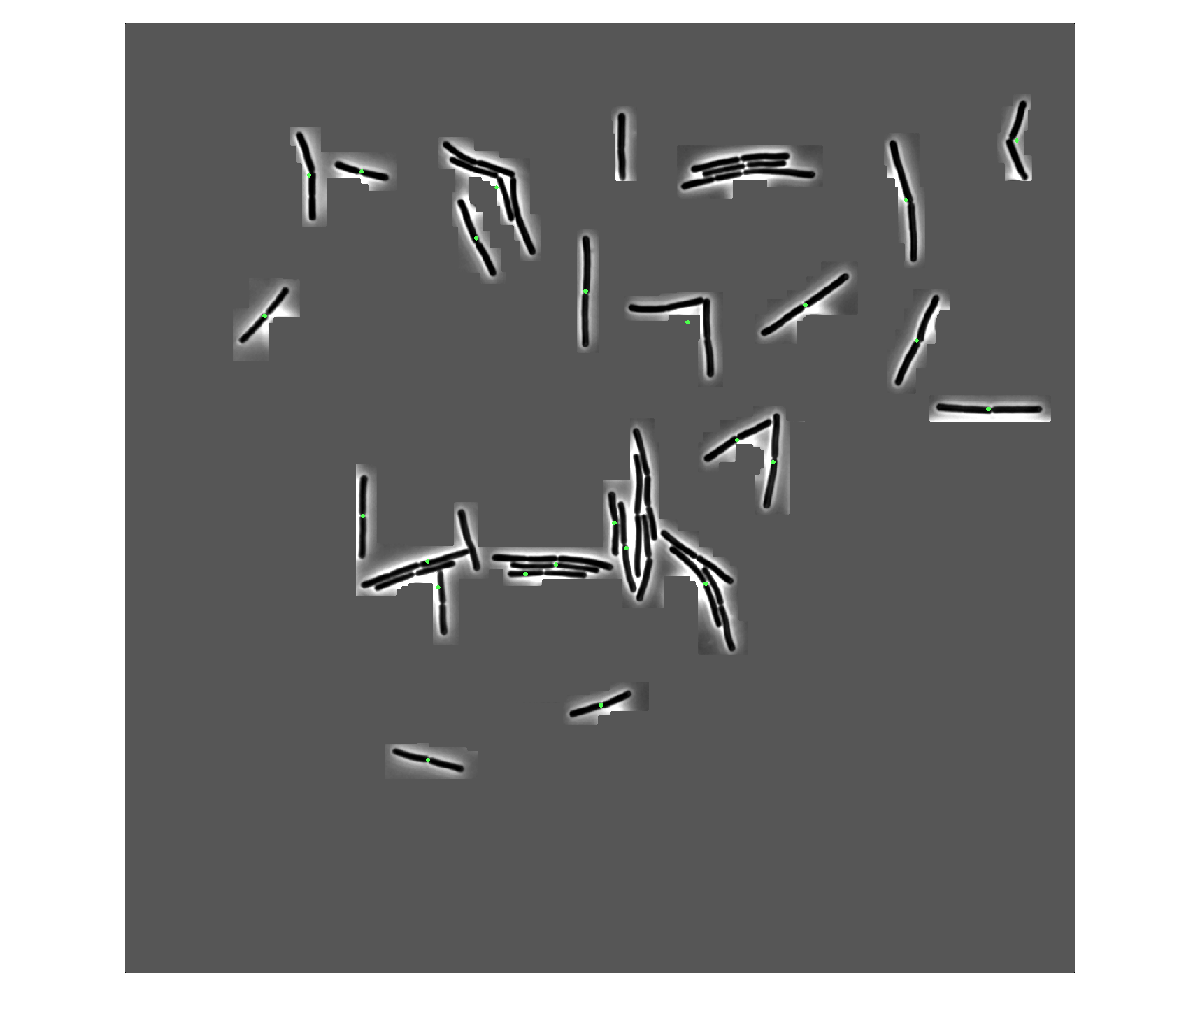

Obtain a label matrix of the connected components in tracks (each centroid) (tracksL) and the number of objects (ncells).  Use the latter variable to pre-allocate the subsequent matricies. The for loop is where everything gets put into order. It is very elegant. 

[tracksL,ncells]=bwlabel(tracks,8);

lcell=zeros(ncells,T);
wcell=zeros(ncells,T);
acell=zeros(ncells,T);
pcell=zeros(ncells,T);
B=cell(ncells,T);
pixels=cell(ncells,T);
mlines=cell(ncells,T);
lcents=length(allcentroids);

for i=1:lcents
    cellid=tracksL(linind(i));
    lcell(cellid,tstamp(i))=l(cellnum(i),tstamp(i));
    wcell(cellid,tstamp(i))=w(cellnum(i),tstamp(i));
    acell(cellid,tstamp(i))=a(cellnum(i),tstamp(i));
    B{cellid,tstamp(i)}=boun{cellnum(i),tstamp(i)};
    pixels{cellid,tstamp(i)}=pxls{cellnum(i),tstamp(i)};
    mlines{cellid,tstamp(i)}=mline{cellnum(i),tstamp(i)};
    pcell(cellid,tstamp(i))=pole(cellnum(i),tstamp(i));
end


Moving on. Throw away cells with only 1-2 time points. How can the 'l' or ''w' variables have elements with 0 value? I'm not sure because these variables were calculated from the midline and width a few sections back. The rest is self-explanatory.

%Throw away cells with only one or two time points
delind=[];

for i=1:ncells
    if length(nonzeros(lcell(i,:)))<=2
        delind=[delind;i];
    end
end

lcell(delind,:)=[];
wcell(delind,:)=[];
acell(delind,:)=[];
pcell(delind,:)=[];
B(delind,:)=[];
pixels(delind,:)=[];
mlines(delind,:)=[];
[ncells,~]=size(lcell);

lcell(lcell==0)=NaN;
wcell(wcell==0)=NaN;
acell(acell==0)=NaN;
pcell(pcell==0)=NaN;

%Dimsionalize the variables
lcell=lcell*lscale;
wcell=wcell*lscale;
acell=acell*lscale^2;

%Throw away cells that are too short or too fat or too skinny
lcell(lcell<minL|wcell>maxW|wcell<minW)=NaN;
wcell(lcell<minL|wcell>maxW|wcell<minW)=NaN;
acell(lcell<minL|wcell>maxW|wcell<minW)=NaN;

This is the last stretch of calculation before we move on to plotting.

Circumferential strian is: 

(Eqxn 1)  width_{i}/mean(width_{i})

Strange. I'd never thought of it that way. Also, note that here, the calculated growth rate IS the elongation rate. 

%Calculate circumferential strain
wcell(isnan(wcell))=0;
ew=zeros(size(lcell));
for i=1:ncells
    ew(i,:)=wcell(i,:)/mean(wcell(i,:));
end

%Calculate the growth rate
deltat=time(2:end)-time(1:end-1);
v=(lcell(:,2:end)-lcell(:,1:end-1))./((lcell(:,1:end-1)+lcell(:,2:end))/2);
av=(acell(:,2:end)-acell(:,1:end-1))./((acell(:,1:end-1)+acell(:,2:end))/2);
for i=1:ncells
    v(i,:)=v(i,:)./deltat;
    av(i,:)=av(i,:)./deltat;
end

%Calculate total length of all cells
lcell(isnan(lcell))=0;
acell(isnan(acell))=0;
for t=1:T
    ltotal(t)=sum(nonzeros(l(:,t)));
    atotal(t)=sum(nonzeros(a(:,t)));
end
lcell(lcell==0)=NaN;
acell(acell==0)=NaN;

%Throw out outliers and calculate the average width,strain and strain rate 
%across cells
v(isnan(v))=0;
av(isnan(av))=0;
ew(isnan(ew))=0;

for t=1:T-1
    vav(t)=mean(nonzeros(v(:,t)));
    vstd(t)=std(nonzeros(v(:,t)));
end
vavm=ones(ncells,1)*vav;
vstdm=ones(ncells,1)*vstd;

inddel=abs(v-vavm)>2*vstdm&vstdm~=0;

v(inddel)=0;
av(inddel)=0;
lcell(inddel)=0;
acell(inddel)=0;
wcell(inddel)=0;
ew(inddel)=0;

for t=1:T
    wav(t)=mean(nonzeros(wcell(:,t)));
    wstd(t)=std(nonzeros(wcell(:,t)));
    wste(t)=wstd(t)./length(nonzeros(wcell(:,t)));
    ewav(t)=mean(nonzeros(ew(:,t)));
    ewstd(t)=std(nonzeros(ew(:,t)));
    ewste(t)=ewstd(t)./length(nonzeros(ew(:,t)));
end
for t=1:T-1
    vav(t)=mean(nonzeros(v(:,t)));
    vstd(t)=std(nonzeros(v(:,t)));
    ndp(t)=length(nonzeros(v(:,t)));
    vste(t)=vstd(t)/sqrt(ndp(t));
    avav(t)=mean(nonzeros(av(:,t)));
    avstd(t)=std(nonzeros(av(:,t)));
    avste(t)=avstd(t)/ndp(t);
end

v(v==0)=NaN;
av(av==0)=NaN;
lcell(lcell==0)=NaN;
wcell(wcell==0)=NaN;
acell(acell==0)=NaN;
ew(ew==0)=NaN;

## Functions

function imout=norm16bit(imin,percent)
%normalizes the intensity of a 16 bit image, saturating a certain 
%percentage of the pixels at the max and min values.

[imcounts,imbin]=hist(double(nonzeros(imin)),1000);
%figure,plot(imbin,imcounts),pause

csic=cumsum(fliplr(imcounts));
pcsic=csic/sum(imcounts);
[~,mpos1]=min(abs(pcsic-percent/100));
maxintensity=imbin(end-mpos1);

csic=cumsum(imcounts);
pcsic=csic/sum(imcounts');
[~,mpos2]=min(abs(pcsic-percent/100));

minintensity=imbin(mpos2);

imout=imadjust(imin,[minintensity/65535 maxintensity/65535],[]);
end

function [X,Y,pole]=polefinder(X,Y);

         K=cellcurvature(X,Y,1);
         lK=length(K);

         sigma=15;
         b=3;
         win=50;
         testx=[-win/2:win/2];
         test=b*exp(-testx.^2/2/(sigma/2).^2);
         cK=conv([K;K;K],test,'same');
         
%          dS=sqrt((X(2:end)-X(1:end-1)).^2+(Y(2:end)-Y(1:end-1)).^2);
%          S=[0 cumsum(dS)']*0.08;
%          figure,plot(S,K),hold on,
%          figure,plot(S,cK(lK+1:2*lK))
%          %figure, hold on, axis equal, axis off,plot(X,Y)
%          %pause
         
         [kmax,imax]=extrema(cK);
         tkmax=imax>lK & imax<=2*lK;
         imax=imax(tkmax);
         
         if length(imax)>1
            poles=imax(1:2)';
         else
            poles(1)=mod(imax(1),lK)+1;
            poles(2)=mod(poles(1)+round(lK/2),lK)+1;
         end
         mpole=min(poles);
         poles=poles-mpole+1;
         pole=max(poles);
         
         X=circshift(X(1:end-1),-mpole);
         Y=circshift(Y(1:end-1),-mpole);
         X=[X;X(1)];
         Y=[Y;Y(1)];
end

%K=cellcurvature(X,Y,neighbor)
%This program calculates the curvature of a cell contour and averages over
%the neighboring points.
%
%INPUT
%X,Y: x and y coordinates of cell boundaries.
%neighbor: number of points to average curvature over.

function K=cellcurvature(X,Y,neighbor)

         [sX,temp]=size(X);

         dX=diff(X);
         dY=diff(Y);
         
         dS=sqrt(dX.^2+dY.^2);
         S=[0 cumsum(dS)'];
         DS=S(end)/(sX-1);
         
         NNx=zeros(sX-1,1);
         NNy=zeros(sX-1,1);
         
         NNx=dY./DS;
         NNy=-dX./DS;
         NN3=[NNx,NNy,zeros(sX-1,1)];
         
         Nlen=sqrt(NNx.^2+NNy.^2);
         
         Ndot=NNx(1:end-1).*NNx(2:end)+NNy(1:end-1).*NNy(2:end);
         Ncross=cross(NN3(1:end-1,:),NN3(2:end,:));
         dphi=acos(Ndot./(Nlen(1:end-1).*Nlen(2:end))).*sign(Ncross(:,3));
         
         K=zeros(sX,1);
         K(2:end-1)=dphi/DS;
         
         K=smooth(K,neighbor,'moving');
end